clear all
rng(3)

xmax = 10

xmax = 10

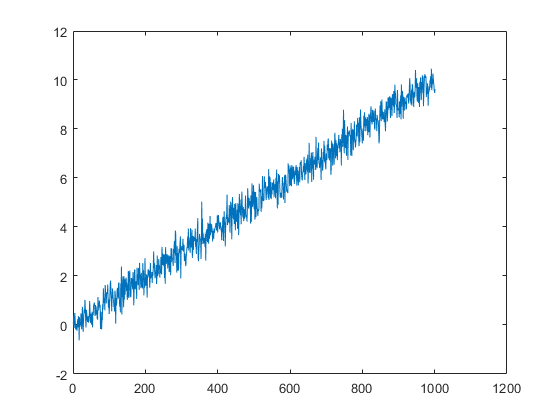

input = ([0:0.01:xmax])';
noise= 0.4*(randn(size(input)));

input1=(input+noise);
plot(input1)


noise= 0.2*(randn(size(input1)));
input2=-noise

input2 =     0.1042
    0.2762
   -0.1165
   -0.1294
    0.0080
    0.0137
    0.0792
   -0.1495
   -0.2963
   -0.0893


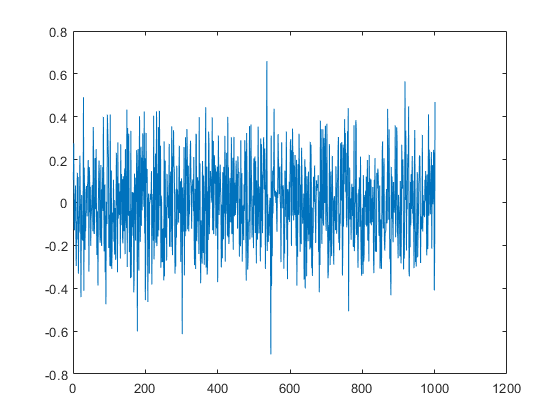

plot(input2)


noise= 0.4*(randn(size(input1)));
input3=(input1+noise).^2

input3 =     0.0430
    0.0112
    0.0106
    0.2596
    0.2584
    0.4003
    0.0044
    0.2940
    0.0752
    0.2363


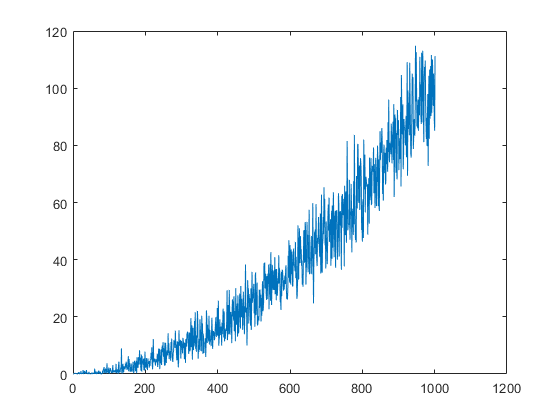

plot(input3)

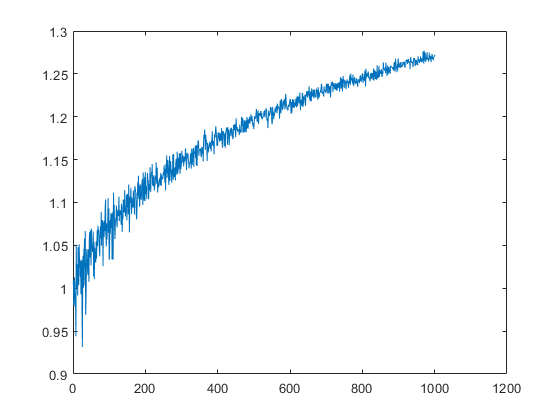


noise= 0.3*(randn(size(input1)));
input4=(input+1+noise).^0.1;
plot(input4)

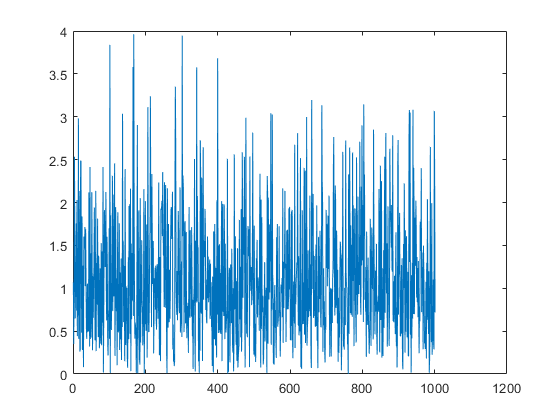


noise= 0.3*(randn(size(input1)));
input5=(input2-1+noise).^2;
plot(input5)


noise= 0.3*(randn(size(input1)));
input6 = 4*input5+noise;

normdata = normalize([input1 input2 input3 input5 input4 input6]);

CORR = abs(corr(normdata))

CORR =     1.0000    0.0104    0.9529    0.0010    0.9491    0.0058
    0.0104    1.0000    0.0029    0.5491    0.0331    0.5451
    0.9529    0.0029    1.0000    0.0032    0.8495    0.0067
    0.0010    0.5491    0.0032    1.0000    0.0103    0.9947
    0.9491    0.0331    0.8495    0.0103    1.0000    0.0061
    0.0058    0.5451    0.0067    0.9947    0.0061    1.0000


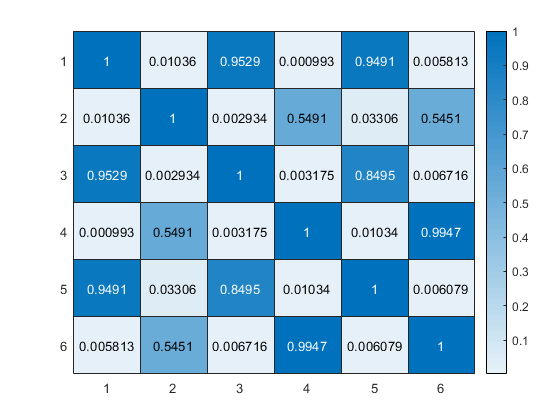

ans =   HeatmapChart with properties:

        XData: {6×1 cell}
        YData: {6×1 cell}
    ColorData: [6×6 double]

  Show all properties


heatmap(CORR)


output= sin((normdata(:,1).^2+sin(normdata(:,2)))).*normdata(:,3)+normdata(:,4).^(3).*normdata(:,5)+0.5*normdata(:,6)+0.01*noise

output =     0.2945
    3.1583
   -0.6751
  -17.3827
   -1.4973
    0.1138
    0.3203
   -0.7774
   -1.6239
   -0.6432


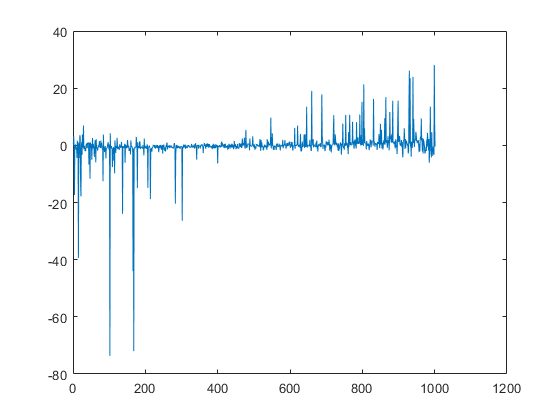


plot(output)


optim = findorder(CORR)

optim =      2
     3
     4
     1
     6
     5



CORR=CORR(:,optim)

CORR =     0.0104    0.9529    0.0010    1.0000    0.0058    0.9491
    1.0000    0.0029    0.5491    0.0104    0.5451    0.0331
    0.0029    1.0000    0.0032    0.9529    0.0067    0.8495
    0.5491    0.0032    1.0000    0.0010    0.9947    0.0103
    0.0331    0.8495    0.0103    0.9491    0.0061    1.0000
    0.5451    0.0067    0.9947    0.0058    1.0000    0.0061


CORR=CORR(optim,:)

CORR =     1.0000    0.0029    0.5491    0.0104    0.5451    0.0331
    0.0029    1.0000    0.0032    0.9529    0.0067    0.8495
    0.5491    0.0032    1.0000    0.0010    0.9947    0.0103
    0.0104    0.9529    0.0010    1.0000    0.0058    0.9491
    0.5451    0.0067    0.9947    0.0058    1.0000    0.0061
    0.0331    0.8495    0.0103    0.9491    0.0061    1.0000


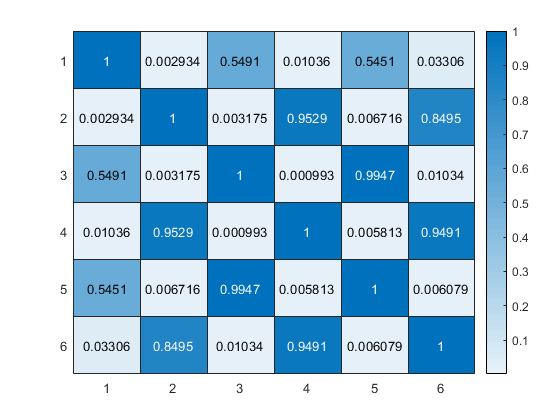

ans =   HeatmapChart with properties:

        XData: {6×1 cell}
        YData: {6×1 cell}
    ColorData: [6×6 double]

  Show all properties


heatmap(CORR)

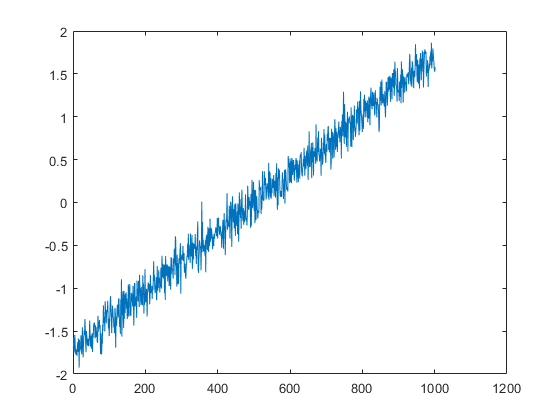

plot(normdata(:,1))

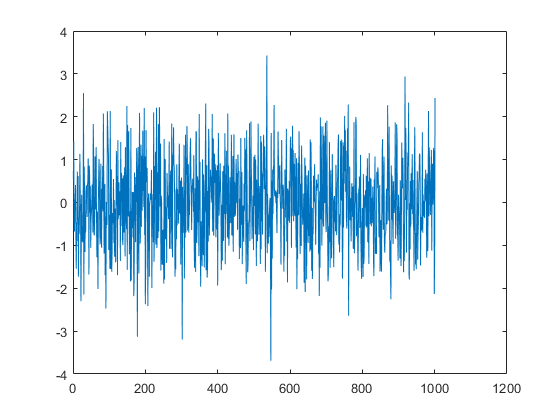

plot(normdata(:,2))

data = (1 + exp(-1 * normdata)).^ -1;
data=data(:,optim);

n = 3;
bs = bspline([0:n+1]);
M = flipud(bs.coefs)';
xmax=1;

knotintervals = 2;
knotdist = xmax/knotintervals;


indexes = floor(data/knotdist)+1;


u = (data/knotdist)-indexes+1;

for  j=1:6
bn = u(:,j).^[n:-1:0]*M;

% B = zeros(length(input),knotintervals+n);
for i=1:length(input)
   B(i,indexes(i,j):indexes(i,j)+n) = bn(i,:);
end
Btot{j}=B;
end

A=[]


A =

     []



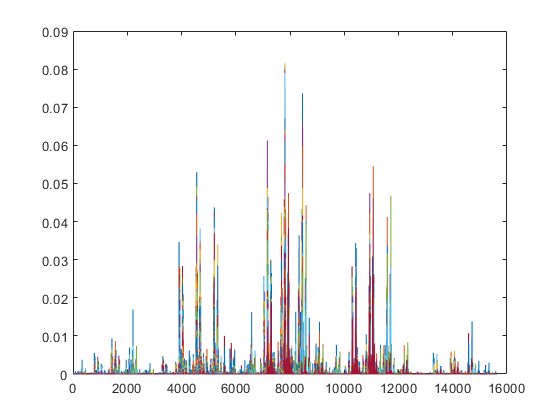

for h=1:length(input)
f= outproduct(Btot{1}(h,:), Btot{2}(h,:), Btot{3}(h,:), Btot{4}(h,:),Btot{5}(h,:),Btot{6}(h,:));

A(h,:)=f(:)';
end
plot(A')



w = pinv(A)*output

w = 	1.0e+03 *

    0.0030
    0.0137
    0.0035
    0.0001
    0.0000
    0.0027
    0.0287
    0.0048
    0.0011
    0.0003


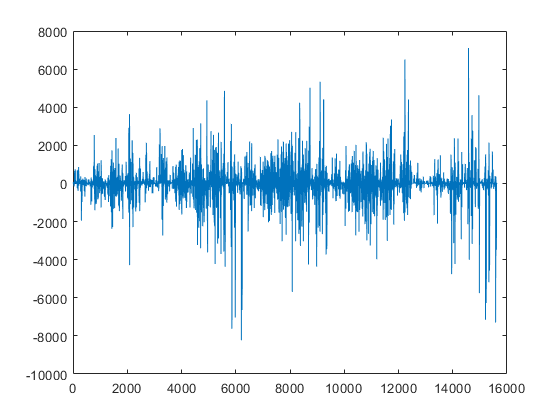

plot(w)

dd= knotintervals+n

dd = 5

W = reshape(w, [dd dd dd dd dd dd])

W = W(:,:,1,1,1,1) =

    2.9863    2.6555    6.2128   10.9686    1.5985
   13.6991   28.6917   29.8327   52.3123    9.0929
    3.5036    4.8419   -5.7825    8.1805    2.1701
    0.1406    1.1392  -12.3427   -6.2258    0.4985
    0.0251    0.3348   -1.8856   -0.8009    0.2559


W(:,:,2,1,1,1) =

    0.0477    7.8890    4.0721    3.2040    0.6253
    1.2980   77.9519   88.8137   38.2165    4.2462
   -5.7526  -81.2057  -58.7932   -7.5741   -7.7830
   -0.7670  -29.8306 -154.5024  -56.0002    5.9803
    0.2891    4.0458  -18.6211   -6.6327    3.2980


W(:,:,3,1,1,1) =

    0.2223    2.0187  -41.3644   14.3245    6.3183
    6.0309  444.6624  179.2465   57.8491   33.1228
   26.0272  662.8095  526.9032   14.2931   -6.2678
    9.8409  161.7910   67.7387  -25.2160   -2.4413
   -0.1478   -4.4544  -16.6016   -3.1630    1.9322


W(:,:,4,1,1,1) =

   16.2851   25.2138   44.3212   42.9618    5.7919
   90.4517  496.1724  523.8146  140.9708   15.2259
   57.3757  744.5908  655.2611   15.6665   -8.6772



e = 0.0001

e = 1.0000e-04

[G, rk] = ttsvd(W,e)

G = 6×1 cell array
    { 1×5×5  double}
    { 5×5×24 double}
    {24×5×73 double}
    {73×5×25 double}
    {25×5×5  double}
    { 5×5    double}


rk =      1
     5
    24
    73
    25
     5



Xrecon = tcontract(G);

relerror = inproduct(W-Xrecon,W-Xrecon)/inproduct(W,W)

relerror = 4.4685e-05

numel(Xrecon)

ans = 15625



plot(w)

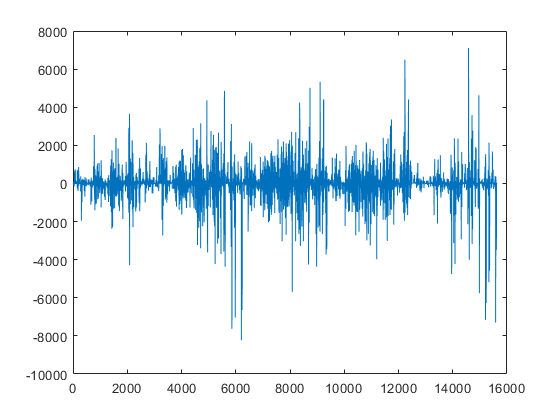

plot(Xrecon(:))


recon = A*w

recon =     0.2945
    3.1583
   -0.6751
  -17.3827
   -1.4973
    0.1138
    0.3203
   -0.7774
   -1.6239
   -0.6432


% hold on
plot(recon);

plot(output);

% hold off

w-Xrecon(:)

ans =     0.5768
    0.9052
   -0.8636
    0.0632
    0.1950
    0.6827
    1.6028
    0.9757
   -0.0038
   -0.3074


recon = A*Xrecon(:)

recon =     0.2912
    3.1545
   -0.6764
  -17.3800
   -1.4971
    0.1088
    0.3167
   -0.7792
   -1.6226
   -0.6468


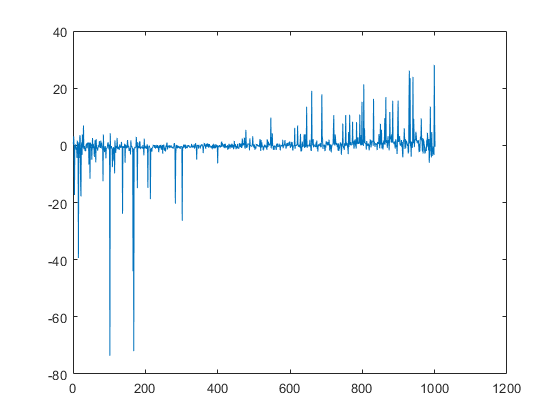

% hold on
plot(recon);

plot(output);

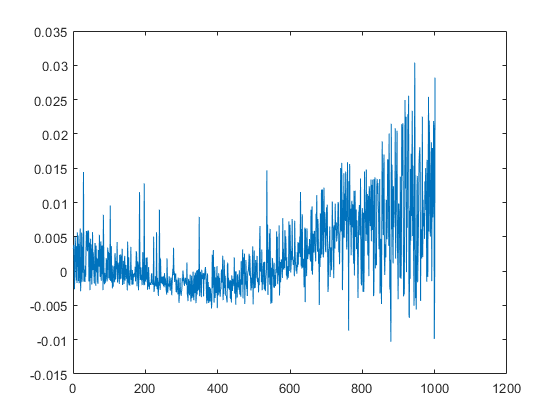

% hold off;

plot(output-recon)



% TESTDATA for generalization test